clear;
A = [0 1; 0 0];
B = [0; 1];
Bw = [1 0; -1 0];
x0 = [0; 0];
w0 = [0; 0];
C = [1 0];
Dw = [0 1];

Cz1 = [-1 2; 0 0];
Dz1 = [0; 1];


Cz2 = [0 0; -2 1];
Dz2 = [1; 0];

%=====Checkers=====
a1 = det(Dz1'*Dz1);
a2 = det(Dz2'*Dz2);
a3 = det(Dw*Dw');
ans_1 = Cz1'*Dz1;
ans_2 = Cz2'*Dz2;
ans_3 = Bw*Dw';
U = [B A*B];
du1 = rank(U);
U2 = [Bw A*Bw];
du2 = rank(U2);
V = [C; C*A];
dv = rank(V);
V1 = [Cz1; Cz1*A];
dv1 = rank(V1);
V2 = [Cz2; Cz2*A];
dv2 = rank(V2);



C_Z = Cz1;
D_Z = Dz1;

% Вычисляем необходимые компоненты
R = D_Z' * D_Z;
Q_riccati = C_Z' * C_Z;

% Решаем уравнение Риккати
[Q,~,K] = icare(A, B, Q_riccati, R, [], [], [], 1);

% Выводим решение
disp('Решение Q:');

Решение Q:


disp(Q);

    4.4495    1.0000
    1.0000    2.4495




K = -pinv(D_Z' * D_Z)*B'*Q;
disp('Решение K:');

Решение K:


disp(K);

   -1.0000   -2.4495



disp(eig(A+B*K));

   -0.5176
   -1.9319




%=====Передаточная функция====
%syms s;
s = tf('s');

%clear sys

%W_wz = simplify((C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw)
W_wz = (C_Z + D_Z*K)*inv(s*eye(2)-A-B*K)*Bw;
H2_norm = norm(W_wz, 2)

H2_norm = 2.2134

trace(Bw'*Q*Bw)^0.5

ans = 2.2134

Hinf_norm = norm(W_wz, inf)

Hinf_norm = 3.5915

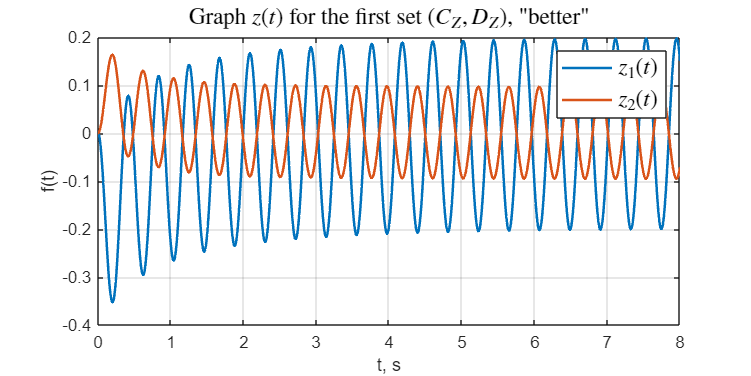


w_s = 0:0.001:10;
%ws11 = subs(W_wz(1,1), s, w_s) 

s_1 = sigma(W_wz, w_s);

%{
figure('Position', [100 100 800 400]);
plot(w_s, s_1, '-', 'LineWidth',2);
grid()
title('Graph $\sigma (\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$\sigma_{1}(\omega)$', '$\sigma_{2}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('$\sigma (abs)$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
%}

%{
syms w real;

ww11 = subs(W_wz(1,1), s, 1j*w) 
ww12 = subs(W_wz(1,2), s, 1j*w)
ww21 = subs(W_wz(2,1), s, 1j*w)
ww22 = subs(W_wz(2,2), s, 1j*w)

P1 = [real(ww11) real(ww12); real(ww21) real(ww22)]

Q1 = [imag(ww11) imag(ww12); imag(ww21) imag(ww22)]



Afc1 = simplify(sqrt(P1.*P1 + Q1.*Q1))


w_x = 0:0.001:10;


Afc11 = double(subs(Afc1(1,1), w, w_x));
Afc12 = double(subs(Afc1(1,2), w, w_x));
Afc13 = double(subs(Afc1(2,1), w, w_x));
Afc14 = double(subs(Afc1(2,2), w, w_x));

figure('Position', [100 100 800 400]);
plot(w_x, Afc11, '-', 'LineWidth',2);
hold on
plot(w_x, Afc12, '--', 'LineWidth',2);
plot(w_x, Afc13, '-.', 'LineWidth',2);
plot(w_x, Afc14, ':', 'LineWidth',2);

grid()
title('Graph $A(\omega)$','Interpreter','latex',  'FontSize', 14)
legend('$A_{11}(\omega)$', '$A_{12}(\omega)$', '$A_{21}(\omega)$', '$A_{22}(\omega)$', 'Interpreter','latex',  'FontSize', 14, 'NumColumns', 2)
ylabel('$|A|$', 'Interpreter','latex')
xlabel('$\omega$, rad/s', 'Interpreter','latex')
hold off
%}

%====AFC=====
%{
simtime = 5;
w = [0:0.0001:simtime];
plot_tf_matrix(sys, w);

n = norm(sys)
nn = norm(sys, Inf)
sq = sqrt(trace(B'*Q*B))
%}
%plot_singular_valies(sys, w);

%=====Simulation=========

open_system('task_1_sim');
set_param('task_1_sim/z', 'VariableName', 'z')
out = sim('task_1_sim');

figure('Position', [100 100 800 400])
plot(out.z,'-', 'LineWidth',1.5);

grid()
title('Graph $z(t)$ for the first set $(C_Z, D_Z)$,  "better"','Interpreter','latex',  'FontSize', 14)
legend('$z_1(t)$', '$z_2(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, s')
hold off